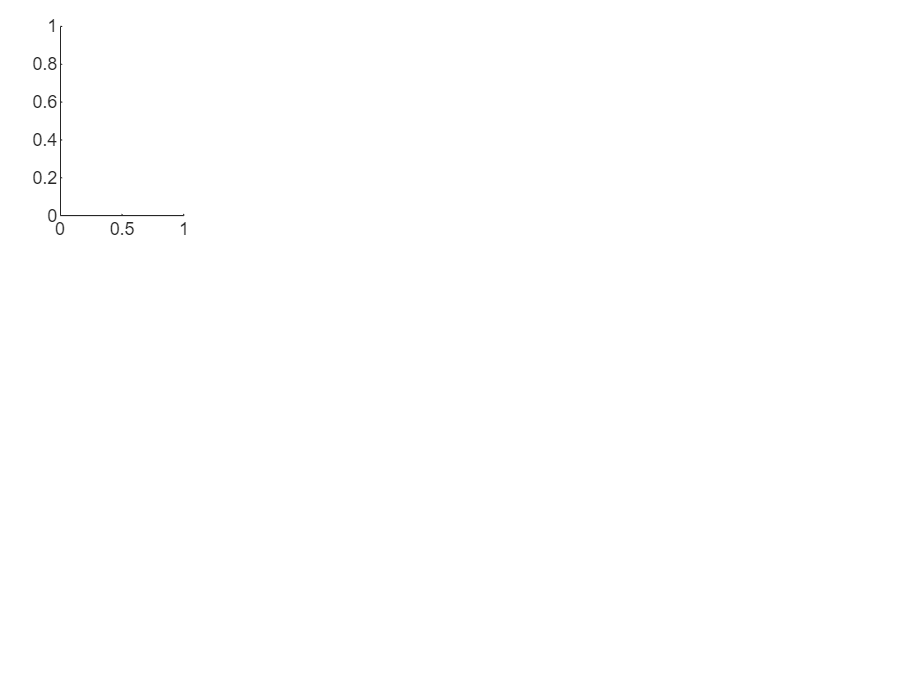

clc; clear all;
fontname("default")

addpath(cd) % in here the file HOA classifier needs to be placed

load("HOA_classifier.mat");

disp('Have you read the ReadMe for correct data stucture?')

Have you read the ReadMe for correct data stucture?




example_data = randn(20 , 1818); %read your actual data here. Needs to be of size n_subjects x 1818.
HOA_classifier = load("HOA_classifier.mat").HOA_classifier;

%either classfiy your subjects with this call or use the script below (same
% script, but with plotting implemented)
% predictions = classify_HOA_patients(example_data, HOA_classifier)

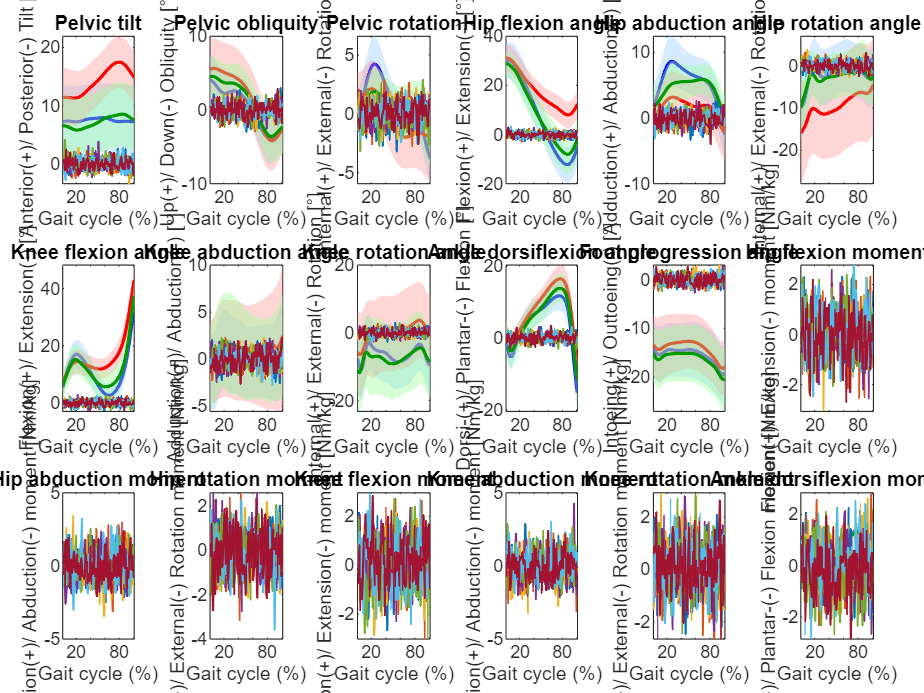


normed_data = (example_data - HOA_classifier.preprocessing.means.mean_health)./HOA_classifier.preprocessing.stds.std_health;

pcs = normed_data * HOA_classifier.preprocessing.eigenvectors.eigenvectors(: , 1:14);

distances = pdist2(pcs(: , 1:14), HOA_classifier.models.kmeans_centroids.centroids_reordered, 'squaredeuclidean');
[~, predicted_cluster] = min(distances, [], 2);

if length(predicted_cluster) < 2
    disp(['Patient belongs to subpopulation ' , num2str(predicted_cluster)])
end

idx1 = find(predicted_cluster == 1);
idx2 = find(predicted_cluster == 2);
idx3 = find(predicted_cluster == 3);

normed_gait_subpopulation_1 = normed_data(idx1 , :);
normed_gait_subpopulation_2 = normed_data(idx2 , :);
normed_gait_subpopulation_3 = normed_data(idx3 , :);

gait_subpopulation_1 = example_data(idx1 , :);
gait_subpopulation_2 = example_data(idx2 , :);
gait_subpopulation_3 = example_data(idx3 , :);

pcs_subpopulation_1 = pcs(idx1 , :);
pcs_subpopulation_2 = pcs(idx2 , :);
pcs_subpopulation_3 = pcs(idx3 , :);

if ~isempty(pcs_subpopulation_1)% ~= 0
    prediction_1 = HOA_classifier.models.svm_subpopulation_1.svm1.predict(pcs_subpopulation_1);
    plot_with_sub_means(HOA_classifier, gait_subpopulation_1, 1)
else
    disp('No Patients were clustered to Subpopulation 1')
    prediction_1=[];
end

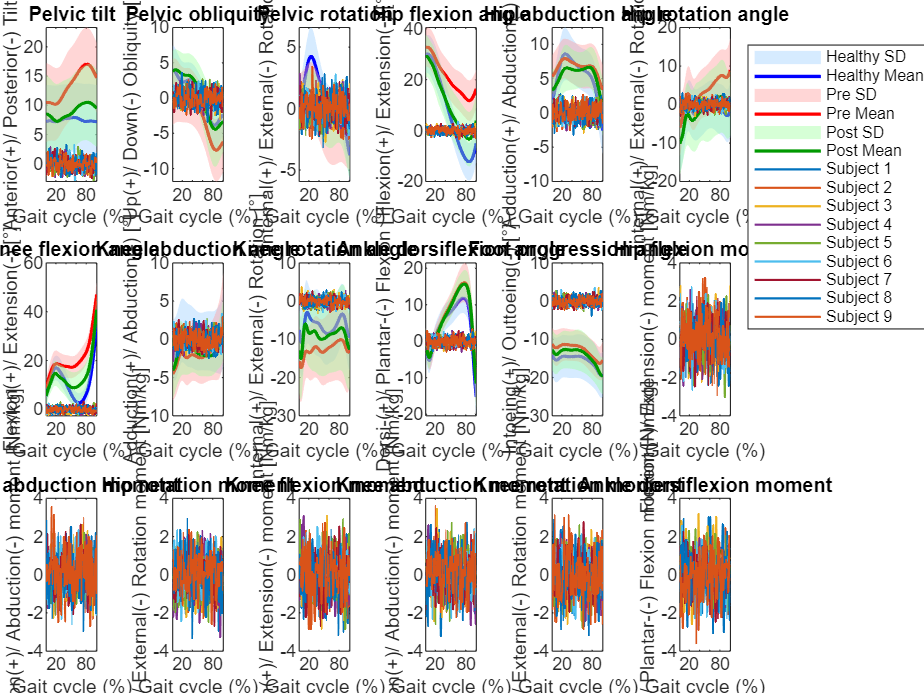


if ~isempty(pcs_subpopulation_2)% ~= 0
    prediction_2 = HOA_classifier.models.svm_subpopulation_2.svm2.predict(pcs_subpopulation_2);
    plot_with_sub_means(HOA_classifier, gait_subpopulation_2, 2)
else
    disp('No Patients were clustered to Subpopulation 2')
    prediction_2=[];
end

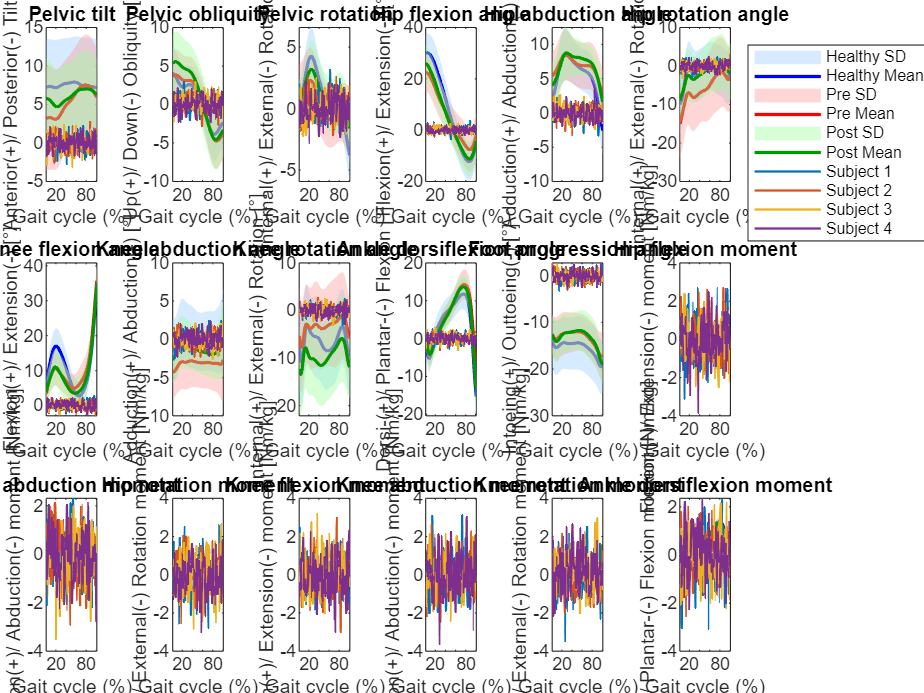



if ~isempty(pcs_subpopulation_3)% ~= 0
    prediction_3 = HOA_classifier.models.svm_subpopulation_3.svm3.predict(pcs_subpopulation_3);
    plot_with_sub_means(HOA_classifier, gait_subpopulation_3, 3)
else
    disp('No Patients were clustered to Subpopulation 3')
    prediction_3=[];
end



predictions = struct();
predictions.subpopoulation_1.gait_data = gait_subpopulation_1;
predictions.subpopoulation_1.normed_gait_data = normed_gait_subpopulation_1;
predictions.subpopoulation_1.pcs = pcs_subpopulation_1;
predictions.subpopoulation_1.prediction = prediction_1;
predictions.subpopoulation_2.gait_data = gait_subpopulation_2;
predictions.subpopoulation_2.normed_gait_data = normed_gait_subpopulation_2;
predictions.subpopoulation_2.pcs = pcs_subpopulation_2;
predictions.subpopoulation_2.prediction = prediction_2;
predictions.subpopoulation_3.gait_data = gait_subpopulation_3;
predictions.subpopoulation_3.normed_gait_data = normed_gait_subpopulation_3;
predictions.subpopoulation_3.pcs = pcs_subpopulation_3;
predictions.subpopoulation_3.prediction = prediction_3;

function plot_predictions_to_sub_and_healthy

variable_names = {'Pelvic tilt' , 'Pelvic obliquity' , 'Pelvic rotation' , 'Hip flexion angle' , 'Hip abduction angle' , 'Hip rotation angle' , ...
     'Knee flexion angle' , 'Knee abduction angle' , 'Knee rotation angle' , 'Ankle dorsiflexion angle' , 'Foot progression angle'};
variable_namesdyn = {'Hip flexion moment' , 'Hip abduction moment' , 'Hip rotation moment' , ...
     'Knee flexion moment' , 'Knee abduction moment' , 'Knee rotation moment' , 'Ankle dorsiflexion moment'};
complete_names = [variable_names , variable_namesdyn];
axis_labels = {'Anterior(+)/ Posterior(-) Tilt [°]', 'Up(+)/ Down(-) Obliquity [°]' ,'Internal(+)/ External(-) Rotation [°]' ,...
    'Flexion(+)/ Extension(-) [°]', 'Adduction(+)/ Abduction(-) [°]' ,'Internal(+)/ External(-) Rotation [°]',...
    'Flexion(+)/ Extension(-) [°]', 'Adduction(+)/ Abduction(-) [°]' ,'Internal(+)/ External(-) Rotation [°]',...
    'Dorsi-(+)/ Plantar-(-) Flexion [°]', 'Intoeing(+)/ Outtoeing(-) [°]',...
    'Flexion(+)/ Extension(-) moment [Nm/kg]', 'Adduction(+)/ Abduction(-) moment [Nm/kg]' ,'Internal(+)/ External(-) Rotation moment [Nm/kg]',...
    'Flexion(+)/ Extension(-) moment [Nm/kg]', 'Adduction(+)/ Abduction(-) moment [Nm/kg]' ,'Internal(+)/ External(-) Rotation moment [Nm/kg]',...
    'Dorsi-(+)/ Plantar-(-) Flexion moment [Nm/kg]'}
vars = length(complete_names);
random_subjects = randperm(20,5);
random_wf = pre1ts(random_subjects , :)
subject_labels = strcat("Subject ", string(random_subjects));

for i = 1:3%vars

    figure; hold on

    idx = (i-1)*101 + (1:101);

    data_mean = mean_pre_1(:, idx);
    data_std  = std_pre_1(:, idx);

    data_health_mean = mean_healthcomp(:, idx);
    data_health_std  = std_healthcomp(:, idx);

    x = 1:101;

    % Patient band
    upper = data_mean + data_std;
    lower = data_mean - data_std;

    % Healthy band
    upper_h = data_health_mean + data_health_std;
    lower_h = data_health_mean - data_health_std;
    % Mean curves
    plot(x, data_health_mean, 'b', 'LineWidth',2, 'color' , 'blue');

    % Healthy shaded area
    fill([x fliplr(x)], [upper_h fliplr(lower_h)], [0.6 0.8 1], ...
        'EdgeColor','none', 'FaceAlpha',0.4);

    plot(x, data_mean, 'Color', [1 0 0], 'LineWidth', 2);

    % Patient shaded area
    fill([x fliplr(x)], [upper fliplr(lower)], [1 0.6 0.6], ...
        'EdgeColor','none', 'FaceAlpha',0.4);
    plot(transpose(random_wf(: , idx)))


    xlabel('Gait cycle (%)')
    ylabel(axis_labels{i})
    title(complete_names{i})

    xlim([1 101])
    legend(['Healthy Mean','Healthy SD','Patient Mean','Patient SD', subject_labels], ...
       'Location','northeastoutside')

    box on

end
end